## Problem 2


$$\left[\matrix{ -M_A\omega^2+\gamma_2+\gamma_1 & -\gamma_1 & -\gamma_2 e^{-ika}\cr -\gamma_1 & -M_B\omega^2+2\gamma_1 & -\gamma_1\cr -\gamma_2 e^{ika} & -\gamma_1 & -M_A\omega^2+\gamma_1+\gamma_2} \right] \left[\matrix { u_{A1}\cr u_B\cr u_{A2}}\right]= 0$$


clc
clear
close all


$$M_A/M_B = 1$$



$$\gamma_1/\gamma_2 = 1$$


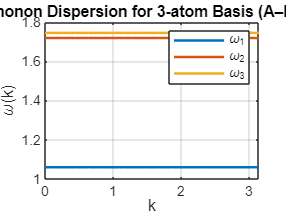

gamma1 = 1;
gamma2 = 1;
MA = 1;
MB = 1;
a = 1;

k = linspace(0, pi/a, 50); % 50 k-values
w = zeros(length(k), 3);   % Preallocate 50x3 matrix for roots

% Constant coefficients
A = -MA^2 * MB;
B = (2 * MA^2 * gamma1) + (2 * MA * MB * gamma1) * (2 * MA * MB * gamma2);
C = (-2 * MA * gamma1^2) - (4 * MA * gamma1 * gamma2) - (MB * gamma1^2) - (2 * MB * gamma1 * gamma2);

for i = 1:length(k)
    D = (-2 * gamma1^2 * gamma2 * cos(k * a)) + (2 * gamma1^2 * gamma2);

    coeffs = [A, B, C, D];
    roots_i = roots(coeffs);

    % Filter real, non-negative roots and take sqrt to get ω
    omega_sq = real(roots_i(imag(roots_i) == 0 & real(roots_i) >= 0));
    omega_sq = sort(omega_sq); % Optional: sort low to high
    n_roots = length(omega_sq);
    w(i, 1:n_roots) = sqrt(omega_sq);
end

% Plot the three branches
figure;
plot(k, w, 'LineWidth', 1.5);
xlabel('k'); ylabel('\omega(k)');
title('Phonon Dispersion for 3-atom Basis (A–B–A)');
legend('\omega_1', '\omega_2', '\omega_3');
grid on;


$$M_A/M_B = 10$$



$$\gamma_1/\gamma_2 = 1$$


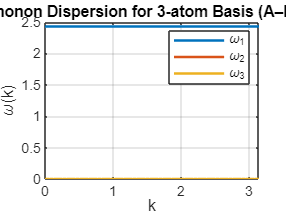

gamma1 = 1;
gamma2 = 1;
MA = 10;
MB = 1;

w = zeros(length(k), 3);   % Preallocate 50x3 matrix for roots

% Constant coefficients
A = -MA^2 * MB;
B = (2 * MA^2 * gamma1) + (2 * MA * MB * gamma1) * (2 * MA * MB * gamma2);
C = (-2 * MA * gamma1^2) - (4 * MA * gamma1 * gamma2) - (MB * gamma1^2) - (2 * MB * gamma1 * gamma2);

for i = 1:length(k)
    D = (-2 * gamma1^2 * gamma2 * cos(k * a)) + (2 * gamma1^2 * gamma2);

    coeffs = [A, B, C, D];
    roots_i = roots(coeffs);

    % Filter real, non-negative roots and take sqrt to get ω
    omega_sq = real(roots_i(imag(roots_i) == 0 & real(roots_i) >= 0));
    omega_sq = sort(omega_sq); % Optional: sort low to high
    n_roots = length(omega_sq);
    w(i, 1:n_roots) = sqrt(omega_sq);
end

% Plot the three branches
figure;
plot(k, w, 'LineWidth', 1.5);
xlabel('k'); ylabel('\omega(k)');
title('Phonon Dispersion for 3-atom Basis (A–B–A)');
legend('\omega_1', '\omega_2', '\omega_3');
grid on;


$$M_A/M_B = 1$$



$$\gamma_1/\gamma_2 = 10$$


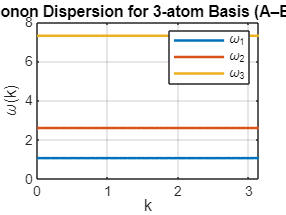

gamma1 = 10;
gamma2 = 1;
MA = 1;
MB = 1;

w = zeros(length(k), 3);   % Preallocate 50x3 matrix for roots

% Constant coefficients
A = -MA^2 * MB;
B = (2 * MA^2 * gamma1) + (2 * MA * MB * gamma1) * (2 * MA * MB * gamma2);
C = (-2 * MA * gamma1^2) - (4 * MA * gamma1 * gamma2) - (MB * gamma1^2) - (2 * MB * gamma1 * gamma2);

for i = 1:length(k)
    D = (-2 * gamma1^2 * gamma2 * cos(k * a)) + (2 * gamma1^2 * gamma2);

    coeffs = [A, B, C, D];
    roots_i = roots(coeffs);

    % Filter real, non-negative roots and take sqrt to get ω
    omega_sq = real(roots_i(imag(roots_i) == 0 & real(roots_i) >= 0));
    omega_sq = sort(omega_sq); % Optional: sort low to high
    n_roots = length(omega_sq);
    w(i, 1:n_roots) = sqrt(omega_sq);
end

% Plot the three branches
figure;
plot(k, w, 'LineWidth', 1.5);
xlabel('k'); ylabel('\omega(k)');
title('Phonon Dispersion for 3-atom Basis (A–B–A)');
legend('\omega_1', '\omega_2', '\omega_3');
grid on;


$$M_A/M_B = 10$$



$$\gamma_1/\gamma_2 = 10$$


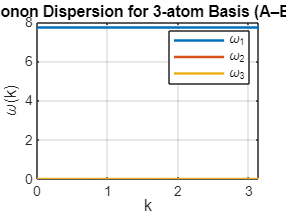

gamma1 = 10;
gamma2 = 1;
MA = 10;
MB = 1;

w = zeros(length(k), 3);   % Preallocate 50x3 matrix for roots

% Constant coefficients
A = -MA^2 * MB;
B = (2 * MA^2 * gamma1) + (2 * MA * MB * gamma1) * (2 * MA * MB * gamma2);
C = (-2 * MA * gamma1^2) - (4 * MA * gamma1 * gamma2) - (MB * gamma1^2) - (2 * MB * gamma1 * gamma2);

for i = 1:length(k)
    D = (-2 * gamma1^2 * gamma2 * cos(k * a)) + (2 * gamma1^2 * gamma2);

    coeffs = [A, B, C, D];
    roots_i = roots(coeffs);

    % Filter real, non-negative roots and take sqrt to get ω
    omega_sq = real(roots_i(imag(roots_i) == 0 & real(roots_i) >= 0));
    omega_sq = sort(omega_sq); % Optional: sort low to high
    n_roots = length(omega_sq);
    w(i, 1:n_roots) = sqrt(omega_sq);
end

% Plot the three branches
figure;
plot(k, w, 'LineWidth', 1.5);
xlabel('k'); ylabel('\omega(k)');
title('Phonon Dispersion for 3-atom Basis (A–B–A)');
legend('\omega_1', '\omega_2', '\omega_3');
grid on;